# EMAT30007 Applied Statistics

# Worksheet 3: Confidence Intervals

## Nikolai Bode

This worksheet focusses on the material covered in Lecture 3: quantifying the uncertainty of an estimated quantity.

## 1. z-CI and t-CI for the mean of a Normal RV

(CI = Confidence Interval)

Consider a normally distributed RV, $X$, such that $X~N\left(0,1\right)$.

- Generate 10000 sets of samples from $X$, each of size $n$, and plot the sampling distribution of the mean for different values of the sample size $n\in \left\lbrack 5,20,100\right\rbrack$.

- Use the empirical quantiles to compute the empirical CIs for the various $n$ for a 95% confidence level $\alpha =0\ldotp 05$.

- Build the z-CI (Lecture 3 Eq.(1)) and t-CI (Lecture 3 Eq.(2)) for each of the samples, using the formulae. Is the length of the empirical CIs close to that of the z-CIs? And of the t-CIs?

- How many estimated z-CIs contain the true value? (For how many estimates does the true value fall inside the z-CI ?) and the t-CIs?

***Solution***

clear
% Normal RV
true_mu = 0;
true_sigma = 1;
pd = makedist('Normal', 'mu', true_mu, 'sigma', true_sigma);
% sampling distribution
% generate samples and estimates
ns = [5 20 100]; % size of samples
S = 10000; % number of samples
estimates = zeros(length(ns), S);
sample_stdevs = zeros(length(ns), S);
for i = 1:length(ns)
    n = ns(i);
    for j = 1:S
        % sample from the normal RV
        x = random(pd, 1, n);
        % compute the estimate for the sample
        estimates(i, j) = mean(x);
        sample_stdevs(i, j) = std(x);
    end
end

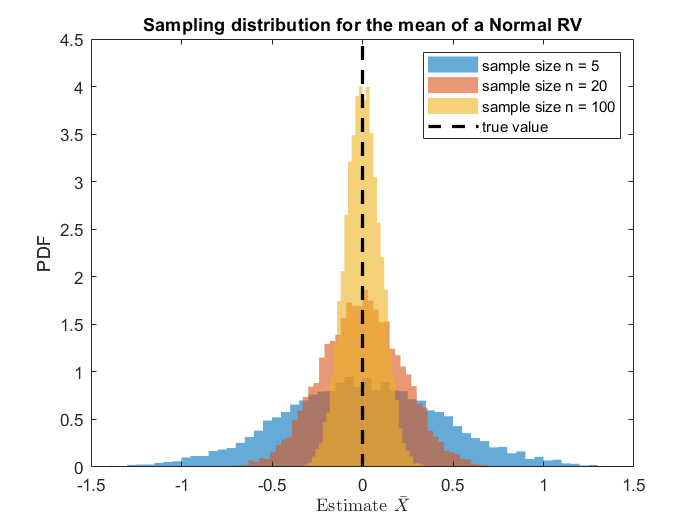

% plot the sampling distributions
clf;
for i = 1:length(ns)
    x = estimates(i, :);
    histogram(x, 'Normalization', "pdf", 'EdgeColor','none');
    hold on
end
yL = get(gca,'YLim');
line([true_mu,true_mu],yL,'Color','k','LineWidth',2,'LineStyle','--')
hold on
xlim([-1.5 1.5]);
title('Sampling distribution for the mean of a Normal RV') %, 'Interpreter', 'latex')
legend('sample size n = 5', 'sample size n = 20', 'sample size n = 100', 'true value');
xlabel('Estimate $\bar{X}$', 'Interpreter', 'latex');
ylabel('PDF');
set(gca, 'FontSize', 10.0);

% compute empirical Confidence Intervals
clf
alpha = 0.05;
eCIs = zeros(length(ns), 2);
for i = 1:length(ns)
    eCIs(i, 1) = quantile(estimates(i, :), alpha / 2);
    eCIs(i, 2) = quantile(estimates(i, :), 1 - alpha / 2);
    % lengths
    eCIs(i, 2) - eCIs(i, 1)
    % plot pdf
    x = estimates(i, :);
    histogram(x, 'Normalization', "pdf", 'EdgeColor','none');
    hold on
end

ans = 1.7849

ans = 0.8791

ans = 0.3871

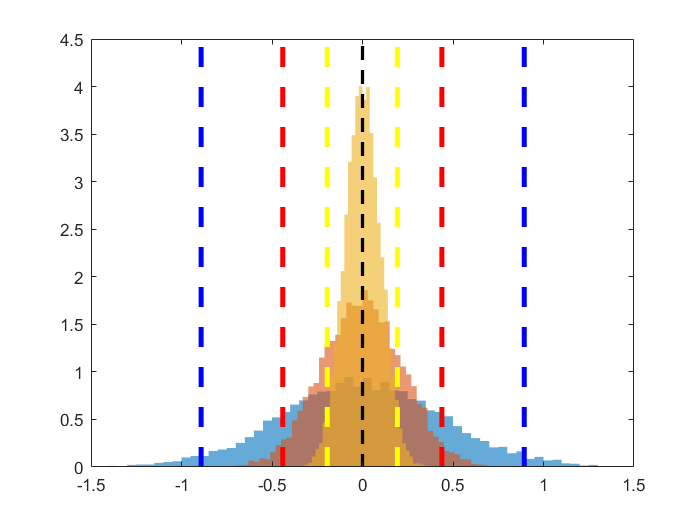

yL = get(gca,'YLim');
line([true_mu,true_mu],yL,'Color','k','LineWidth',2,'LineStyle','--')
hold on
%xline(eCIs(1, 1), '--b', 'Linewidth', 3,'HandleVisibility','off');
%xline(eCIs(1, 2), '--b', 'Linewidth', 3,'HandleVisibility','off');
line([eCIs(1, 1),eCIs(1, 1)],yL,'Color','b','LineWidth',3,'LineStyle','--')
line([eCIs(1, 2),eCIs(1, 2)],yL,'Color','b','LineWidth',3,'LineStyle','--')
hold on
%xline(eCIs(2, 1), '--r', 'Linewidth', 3,'HandleVisibility','off');
%xline(eCIs(2, 2), '--r', 'Linewidth', 3,'HandleVisibility','off');
line([eCIs(2, 1),eCIs(2, 1)],yL,'Color','r','LineWidth',3,'LineStyle','--')
line([eCIs(2, 2),eCIs(2, 2)],yL,'Color','r','LineWidth',3,'LineStyle','--')
hold on
%xline(eCIs(3, 1), '--y', 'Linewidth', 3,'HandleVisibility','off');
%xline(eCIs(3, 2), '--y', 'Linewidth', 3,'HandleVisibility','off');
line([eCIs(3, 1),eCIs(3, 1)],yL,'Color','y','LineWidth',3,'LineStyle','--')
line([eCIs(3, 2),eCIs(3, 2)],yL,'Color','y','LineWidth',3,'LineStyle','--')
xlim([-1.5 1.5]);


% compute the z-CI (Lecture 3, Eq. 1) for each sample
zCIs1 = zeros(length(ns), S); % lower edges
zCIs2 = zeros(length(ns), S); % upper edges
for i = 1:length(ns)
    zCIs1(i, :) = estimates(i, :) - norminv(1 - alpha / 2) * 1 / (ns(i))^0.5;
    zCIs2(i, :) = estimates(i, :) - norminv(alpha / 2) * 1 / (ns(i))^0.5;
    % average lengths
    mean(zCIs2(i, :) - zCIs1(i, :), 2)
end

ans = 1.7530

ans = 0.8765

ans = 0.3920

% fraction of intervals that contain the true mean, for the various sizes n
mean(zCIs1 < true_mu & true_mu < zCIs2, 2) % mean over the second dimension (axis)

ans =     0.9468
    0.9491
    0.9523


The size of the zCIs are very similar to those of the empirical CIs.

The fractions of intervals containing the true value are all close to 0.95, the expected number for a 95% confidence level.

% compute the t-CI (Lecture 3, Eq. 2) for each sample
tCIs1 = zeros(length(ns), S); % lower edges
tCIs2 = zeros(length(ns), S); % upper edges
for i = 1:length(ns)
    tCIs1(i, :) = estimates(i, :) - tinv(1 - alpha / 2, ns(i) - 1) * sample_stdevs(i, :) / (ns(i))^0.5;
    tCIs2(i, :) = estimates(i, :) - tinv(alpha / 2, ns(i) - 1) * sample_stdevs(i, :) / (ns(i))^0.5;
    % average sizes
    mean(tCIs2(i, :) - tCIs1(i, :), 2)
end

ans = 2.3285

ans = 0.9286

ans = 0.3956

% fraction of intervals that contain the true mean, for the various sizes n
mean(tCIs1 < true_mu & true_mu < tCIs2, 2) % mean over the second dimension (axis)

ans =     0.9495
    0.9527
    0.9516


The size of the tCIs are bigger than the empirical CIs, especially for small sample sizes n. This means that, while the tCIs do contain the true value 95% of the times, they are larger than the zCIs, for the same n. This originates from the fact that the t-distribution has a larger variance than the standard Normal distribution, especially for small n (see last plot at [https://uk.mathworks.com/help/stats/students-t-distribution.html](https://uk.mathworks.com/help/stats/students-t-distribution.html)). When computing the tCI we had to estimate the standard deviation σ using the data, which introduces more uncertainty in the estimate, and hence larger tCIs are necessary for the same confidence level.

The fractions of intervals containing the true value are all close to 0.95, the expected number for a 95% confidence level.

## 2. CI for the mean of a Bernoulli RV & the Central Limit Theorem

- Central limit theorem (CLT): generate samples from a Bernoulli RV with $p=0\ldotp 4$ and plot the sampling distribution of the mean for different values of the sample size $n$. Show that the sampling distribution approaches a Normal distribution for large $n$.

- Use the empirical quantiles to compute the empirical CIs for the various $n$ for a confidence level $\alpha =0\ldotp 05$.

- Build the z-CI for each sample using the formula Eq.(1) of Lecture 3. Is the mean length of the z-CIs close to that of the the empirical CIs?

- How many estimated z-CI contain the true value? (For how many estimates the true value fall inside the z-CI?)

- Build the t-CI for each sample using the formula Eq.(2) of Lecture 3 and compute the mean lengths and the fraction that contain the true value. What do you observe?

***Solution***

% Solution
% 

## 3. Exercises

**Fruit flies**

An experiment was conducted to determine the effectiveness of heat treatment to kill fruit fly eggs in mangoes. From 5903 eggs in treated mangoes, 637 adults hatched. What is the probability $p$ that an egg will survive the heat treatment?

- Work out an estimate for $p$.

- Work out a standard deviation for the estimate $p$.

- Work out a 99% confidence interval for $p$.

***Solution***

**Call centre**

The call centre for a bank samples $n=58$ incoming phone calls and records the time taken to answer each. It is found that the average call time is 99 seconds and the variance is estimated to be 576 sec. Find a 90% confidence interval for the mean call time. (List the assumptions you make.)

***Solution***

## 4. When the t-CI fails: the mean of a Pareto distribution

- Generate samples from a Pareto distribution $P_X \left(x;\theta \right)=\frac{\theta }{x^{\theta +1} }$ for $x>1$ with $\theta =1\ldotp 5$ (use the code` x = rand(1, n) .^ (-1/theta)`; from Lab 2) and plot the sampling distribution of the mean for different values of the sample size $n$. Is the sampling distribution of symmetric for small $n$? Does it approach a Normal distribution for large $n$?

- Use the empirical quantiles of the sampling distribution to compute the empirical CIs of the mean for the various $n$ for a confidence level $\alpha =0\ldotp 05$. Are the CIs symmetric with respect to the true value? (why?)

- Build the t-CI for each sample. Is the mean length of the t-CIs close to that of the the empirical CIs?

- How many estimated t-CI contain the true value? (For how many estimates the true value fall inside the t-CI?)

***Solution***

## 5. Bootstrapping

**Bootstrap-CI for the mean of a Normal RV**

- Plot the empirical sampling distribution for the mean of a Normal RV with $\mu =0$  and $\sigma =1$ (see Exercise 1) generating $S=1000$ samples of size $n=5$.

- Plot the bootstrap distribution obtained generating bootstrap samples, where each sample is generated by drawing n elements with replacement from an original sample of size n

- Compare the sampling and bootstrap distributions: do they have the same mean? do they have the same spread? Do your answers change if you vary n?

- Compute the bootstrap-CI for a 50% confidence level and add 3 vertical lines (one for the true value and two for the boot-CI) to the plot with the sampling and bootstrap distribution.

- Repeat steps 1-4 a few times and count the fraction of boot-CI that don't contain the true value: are they rhoughly 50%?

- Write a for loop that repeats steps 2-4 1000 times for a confidence level of 95%: (a) do boot-CIs and empirical CIs have similar length? (b) How many boot-CIs contain the true value? What happens when n increases?

***Solution***

% Normal RV
mu = 0;
sigma = 1;
true_m = mu;
% observed sample
n = 5;
d = normrnd(mu, sigma, 1, n);
S = 1000;
estimates = zeros(1, S);
bootstrap_ests = zeros(1, S);
for i = 1 : S
    % sampling distribution
    x = normrnd(mu, sigma, 1, n); % this is a new sample from the Normal distrib
    estimates(i) = mean(x);
    % bootstrap distribution
    x = datasample(d, n); % this is sampled with replacement from the original data
    bootstrap_ests(i) = mean(x);
end
% compute the boot-CI
alpha = 0.5;
bCI = quantile(bootstrap_ests, [alpha/2 1-alpha/2])

bCI =    -0.1124    0.3571


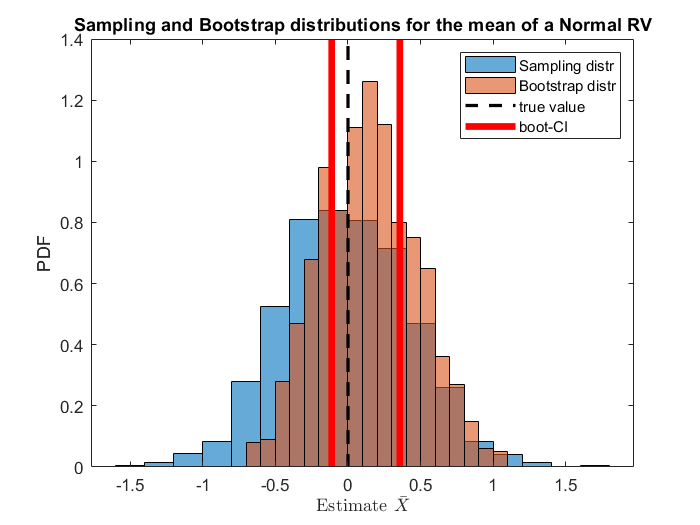

% plot
clf
histogram(estimates, 'normalization', 'pdf')
hold on
histogram(bootstrap_ests, 'normalization', 'pdf')
hold on
yL = get(gca,'YLim');
line([true_m,true_m],yL,'Color','k','LineWidth',2,'LineStyle','--')
%xline(true_m, '--k', 'Linewidth', 3);
hold on
%xline(bCI(1), '-r', 'Linewidth', 4);
line([bCI(1),bCI(1)],yL,'Color','r','LineWidth',4,'LineStyle','-')
hold on
%xline(bCI(2), '-r', 'Linewidth', 4);
line([bCI(2),bCI(2)],yL,'Color','r','LineWidth',4,'LineStyle','-')
title('Sampling and Bootstrap distributions for the mean of a Normal RV') %, 'Interpreter', 'latex')
legend('Sampling distr', 'Bootstrap distr', 'true value', 'boot-CI');
xlabel('Estimate $\bar{X}$', 'Interpreter', 'latex');
ylabel('PDF');
set(gca, 'FontSize', 10.0);

The shape of the bootstrap distribution is similar to the shape of the sampling distribution, especially for large n.

The "spread" (standard deviations) of the two distributions are similar, while the means can be different.

alpha = 0.05;
R = 1000;
bCIs = zeros(R, 2);
for j = 1:R
    % observed sample
    n = 5;
    d = normrnd(mu, sigma, 1, n);
    S = 1000;
    bootstrap_ests = zeros(1, S);
    for i = 1 : S
        % bootstrap distribution
        x = datasample(d, n); % this is sampled with replacement from the original data
        bootstrap_ests(i) = mean(x);
    end
    % compute the boot-CI
    bCIs(j, :) = quantile(bootstrap_ests, [alpha/2 1-alpha/2]);
end
% average size of b-CIs
mean(bCIs(:, 2) - bCIs(:, 1))

ans = 1.4339

% fraction of intervals that contain the true mean, for the various sizes n
mean(bCIs(:, 1) < true_m & true_m < bCIs(:, 2), 1) % mean over the second dimension (axis)

ans = 0.8350

Average length of b-CIs gets closer to that of empirical CI (from Exercise 1) as n increases.

The fraction of b-CIs containing the true value gets closer to the desired confidence level as n increases.

**Bootstrap-CI for the standard deviation of a population**

Use the bootstrap percentile CI to estimate the standard deviation of student heights at 95% confidence level.

The measured heights of random students are:

d = [176, 165, 189, 180, 172, 169, 162, 161, 183, 170];

***Solution***